## Time-frequency analysis 

***Activity time- and non-phase-locked to the event.***

Mathilde Marie Duville

**Notice 1: ***Parallel computing may be implemented to decrease computing time (in case of large datasets; the *Parallel Computing Toolbox must be installed*)*

**Notice 3: **Please, refer to the PowerPoint slide dedicated to it for a visual explanation (TheoreticalExplanations.pdf). 

% mr = mapreducer();

### Morlet Wavelet

Contrary to sine waves that have no temporal localization (frequency and amplitude are repeated without change over time), wavelets waveforms introduce temporal fluctuations of both amplitude and frequency. Morlet wavelets are created by multiplying a sine wave with a Gaussian taper of defined time window. The distribution of the waveform used for windowing (i.e., here Gaussian) defines the wavelet family (i.e., here Morlet). Morlet wavelets are usually used because of their well-suited precision for extracting spectral information in time from EEG data. The peak frequency of the wavelet is defined by the frequency of the sine wave that has been multiplied by the Gaussian window. However, wavelets contain energy over a range of frequencies around the peak frequency, a common characteristic between wavelets and kernels of bandpass filters.

The signal is then convolved with the Morlet wavelet for every frequency of interest. Convolution consists of computing the dot product between the reversed wavelet and the signal and repeating it for sliding windows through the time series. The dot product corresponds to the sample-by-sample multiplication of both signals, and further summation of the resulting samples. The convolution process generates a third time series that is the signal weighted by the spectral characteristics of the wavelet. As the wavelet contains energy over a narrow range of frequencies centered around its peak frequency, the convolved signal expresses the extent to which the original signal contains energy over the spectral range of the wavelet. In that respect, the convolved time series depicts the time-varying mapping between the signal and the wavelet. Therefore, wavelet convolution is very similar to bandpass filtering the signal over the frequency range of the wavelet.

*Important consideration when designing Wavelets:*

- The signal must be of enough duration to contain at least (and preferentially more) 2 cycles of the lowest wavelet peak frequency. For instance, if 4 Hz is the lowest frequency extracted (it means that 1 cycle lasts 0.25 seconds). Thus, at least 0.5 seconds are needed.

- The highest frequency cannot be higher than the Nyquist frequency: you need at least 2 samples per cycle to measure a sine wave. 

- The wavelet should be of enough duration for lowest frequencies (extremities) to taper zero.

- The number of cycles of the Gaussian taper defines the width (and number of cycles) of the Wavelet. It defines time/frequency precision. The temporal precision is defined by: (1/frequency)*number_cycles. Therefore, more cycles allow better frequency precision at the expense of temporal precision, and vice versa. For instance, if the number of cycles per window is 7, the time window is 1000 ms for 7 Hz (1/7 * 7 cycles); 700 ms for 10 Hz (1/10 * 7 cycles) and 350 ms for 20 Hz (1/20 * 7 cycles).

- Extracting more frequencies would improve the smoothness of time-frequency plots. However, because the wavelet contains several frequencies around its peak in the frequency domain, autocorrelation exists between neighbouring frequencies (redundant information). Furthermore, the more frequencies, the more the computation time. 

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

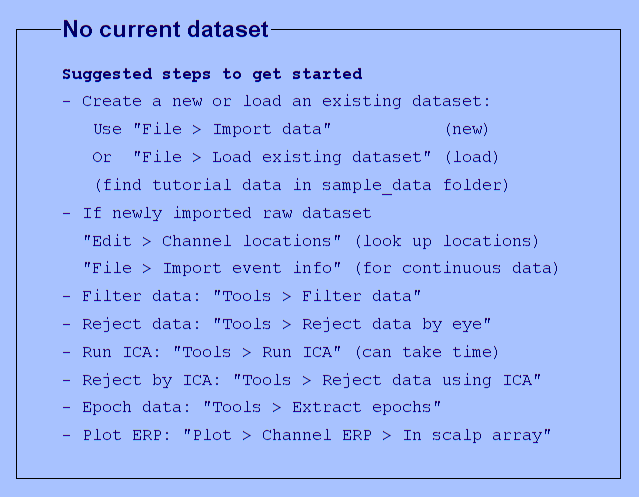

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

*Import previously preprocessed data*

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part22-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part22-Human_Anger.fdt'...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


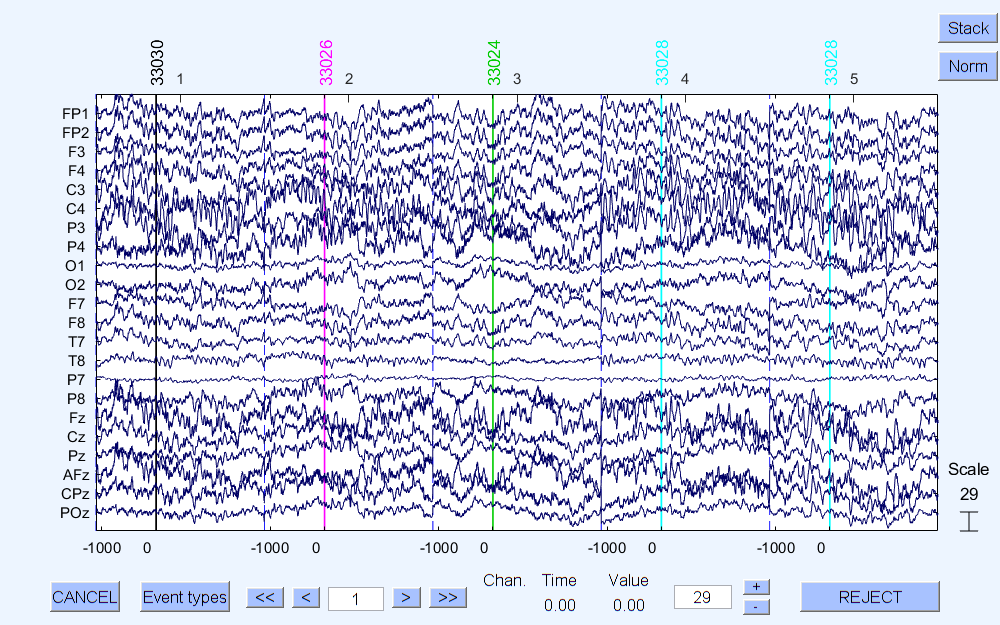

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part33-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part33-Human_Anger.fdt'...


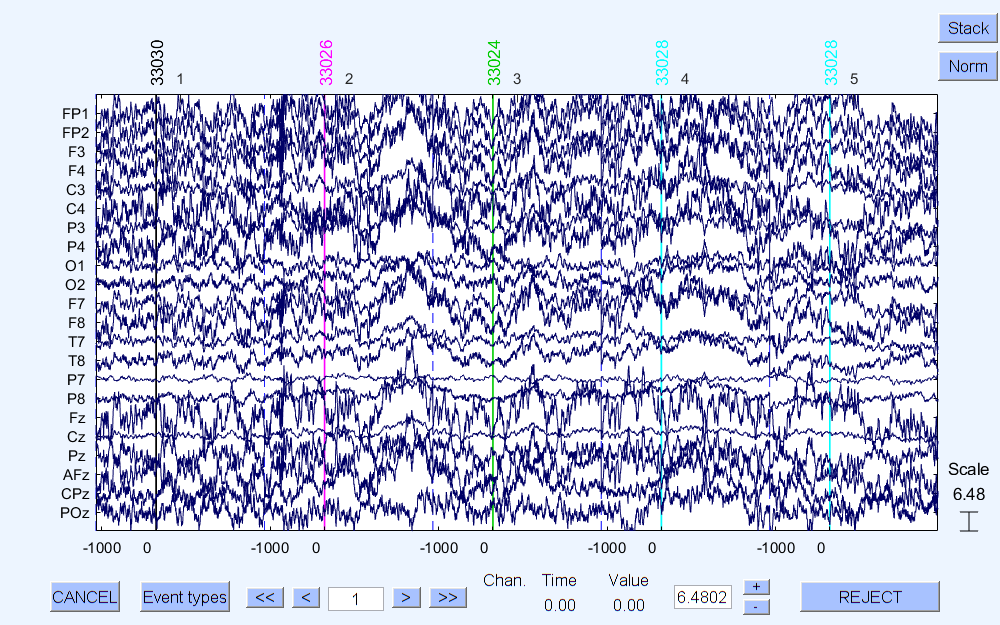

MainPath = pwd; folder = uigetdir(); 
fileList = dir(fullfile(folder, '*.set')); L=length(fileList); n = cell(1,L);
for i = 1:L
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name;
   EEG = []; EEG = pop_loadset('filename', fileList(i).name, 'filepath', MainPath);
   EEG.setname = fileList(i).name; CURRENTSET = []; CURRENTSET = i; 
   [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
   pop_eegplot(EEG, 1, 1, 1); 
end

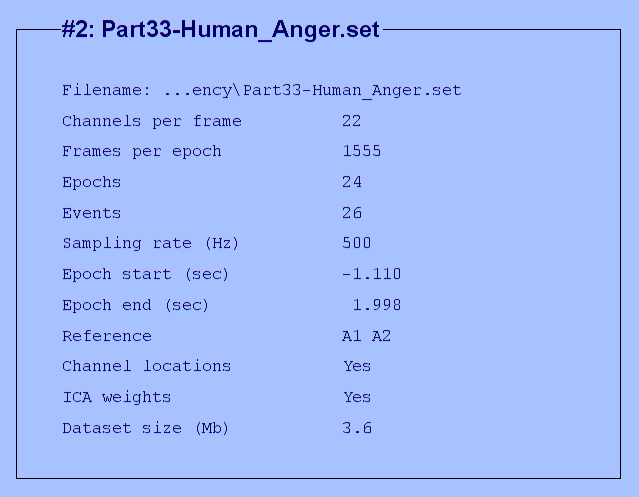

eeglab redraw

#### Time-frequency transform

Time-locked epochs from 1.1 s pre- to 2 s post-stimulus have been previsouly extracted from the preprocessed data. Then, Event-Related Spectral Perturbations (ERSP) are extracted between 4 and 90 Hz by Morlet wavelet expanding from 3 (at 4 Hz) to 67.5 cycles (at 90 Hz) and referenced to the [-1100 -100] ms silent baseline. Namely, a surrogate distribution was created by averaging 200 random samples from the interval between trials and was used to divide data from generated epochs. Permutation statistics are then conducted to depict significant ERSP compared to baseline (1000 iterations, p-value < 0.05). Non-significant data are set to 0. For each participant, ERSP are averaged over trials.

*See the "newtimef" and "pop_newtimef" functions of EEGLab for details about each parameter.*

**************** PART 1 Channel 1 ****************


Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 1551 frames sampled at 500 Hz.
Each trial contains samples from -1100 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 67.5 at highest.
Generating 800 time points (-683.0 to 1583.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 417 samples (834 ms) wide.
Estimating 1377 log-spaced frequencies from 4.0 Hz to 90.0 Hz.
Processing time point (of 800): 10 20 30 40 50 60 70 80 90 100 110 120
 130 140 150 160 170 180 190 200 210 220 230 240
 250 260 270 280 290 300 310 320 330 340 350 360
 370 380 390 400

**************** PART 2 Channel 1 ****************


Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 1551 frames sampled at 500 Hz.
Each trial contains samples from -1100 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 67.5 at highest.
Generating 800 time points (-683.0 to 1583.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 417 samples (834 ms) wide.
Estimating 1377 log-spaced frequencies from 4.0 Hz to 90.0 Hz.
Processing time point (of 800): 10 20 30 40 50 60 70 80 90 100 110 120
 130 140 150 160 170 180 190 200 210 220 230 240
 250 260 270 280 290 300 310 320 330 340 350 360
 370 380 390 400

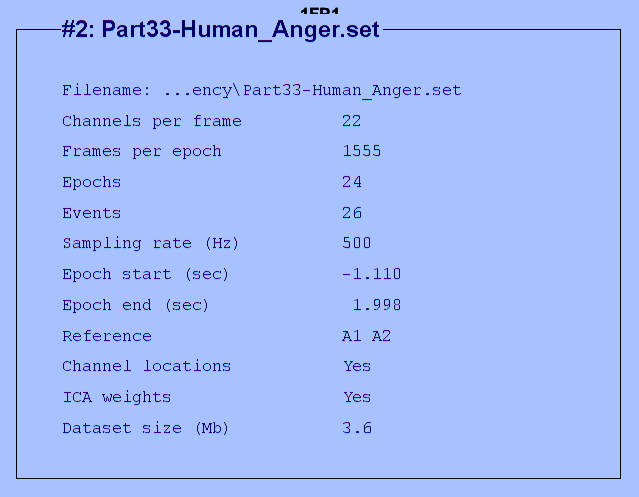

ersp_tot = cell(1,L); itc_tot = cell(1,L);
powbase_tot = cell(1,L);times_tot = cell(1,L); frequencies_tot = cell(1,L);
erspboot_tot = cell(1,L); itcboot_tot = cell(1,L); tfdata_tot = cell(1,L);
itcabs_tot = cell(1,L);
for i = 1:1:L %participants
    ersp = []; itc = []; tfdata = []; powbase = []; times = []; frequencies = [];
    erspboot = []; itcboot = []; EEG = []; EEG = ALLEEG(i); labels = {EEG.chanlocs.labels}'; j = []; 
    for j = 1:1:1%size(labels,1) %sensors - Here, only first sensor to lower computation cost
        disp(['**************** PART ' num2str(i) ' Channel '...
            num2str(j) ' ****************']);
        try[ersp, itc, powbase, times, frequencies, erspboot, itcboot, tfdata] =  ...
            pop_newtimef(EEG, 1, j, [-1100 2000], [3 67.5] ,...
            'topovec', j, 'elocs', EEG.chanlocs, ...
            'chaninfo', EEG.chaninfo, 'caption', [num2str(j)...
            labels{j,1}],'rmerp', 'off', 'detrend', 'off',....
            'baseline', [-1100 -100], 'alpha',0.05, 'plotersp',...
            'off', 'mcorrect', 'none', 'naccu', 1000 ,'baseboot', 1,...
            'boottype' , 'shuffle','plotphase', 'off',...
            'padratio', 16, 'wletmethod' , 'dftfilt3','timesout',800,...
            'freqs', [4 90],'freqscale','log',...
            'cycleinc', 'linear','basenorm', 'off','trialbase', 'off',...
            'plotitc', 'off','winsize', 500);
            ersp_tot{j,i} = ersp; itc_tot{j,i} = itc; powbase_tot{j,i} = powbase;
            times_tot{j,i} = times; frequencies_tot{j,i} = frequencies;
            erspboot_tot{j,i} = erspboot;  itcboot_tot{j,i} =  itcboot;
            tfdata_tot{j,i} =  tfdata; itcabs_tot{j,i} = abs(itc_tot{j,i}); 
        catch 
            disp('error')
        end
    end
end

Save data

% (nfreqs,timesout) matrix of log spectral diffs from baseline (in dB log scale or absolute scale).
% save 01_ersp_tot.mat ersp_tot

% (nfreqs,timesout) matrix of complex inter-trial coherencies.
% save 01_itc_tot.mat itc_tot

% baseline power spectrum.
% save 01_powbase_tot.mat powbase_tot

% vector of output times
% save 01_times_tot.mat times_tot
% save 01_time.mat times

% vector of output frequencies
% save 01_frequencies_tot.mat frequencies_tot
% save 01_frequencies.mat frequencies

% (nfreqs,2) matrix of [lower upper] ERSP significance.
% save 01_erspboot_tot.mat erspboot_tot

% (nfreqs) matrix of [upper] abs(itc) threshold.
% save 01_itcboot_tot.mat itcboot_tot

% optional (nfreqs,timesout,trials) time/frequency decomposition of the single data trials. Values are complex.
% save 01_tfdata_tot_sadness.mat tfdata_tot

% magnitude of ITC: absolute values
% save 01_itcabs_tot.mat itcabs_tot

% channels info
chanlocs = EEG.chanlocs;
% save chanlocs.mat chanlocs

**Note: Another code for creating Morlet wavelets outside of the EEGLab function is available in the next section. **

Outline significant ERSP

clc; clear; close all; load('01_ersp_tot.mat'); load('01_erspboot_tot.mat');

ersp_boot = cell(size(ersp_tot,1),size(ersp_tot,2));
for m = 1:1:size(ersp_tot,2) %participants
    for k = 1:1:size(ersp_tot,1) %sensors
        ersp_tot2 = []; ersp_tot2 = ersp_tot{k,m}; 
        f = []; f = erspboot_tot{k,m}; i = []; 
        for i = 1:1:size(ersp_tot2,2) %time
            j = []; 
            for j = 1:1:size(ersp_tot2,1) %frequencies
                e = []; e = ersp_tot2(j,i);
                % Whenever ERSP is not inferior nor superior to the
                % threshold for significance (non-significant data)
                if e < f(j,1) == 0 && e > f(j,2) == 0 
                    ersp_tot2(j,i) = 0;
                end
            end
        end
        ersp_boot{k,m} = ersp_tot2;
    end
end
%

% save 01_ersp_boot.mat ersp_boot

Figure per participant and channel

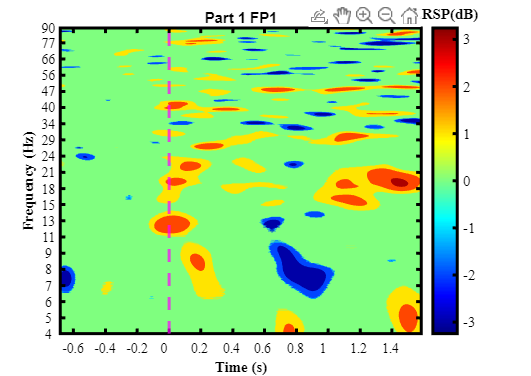

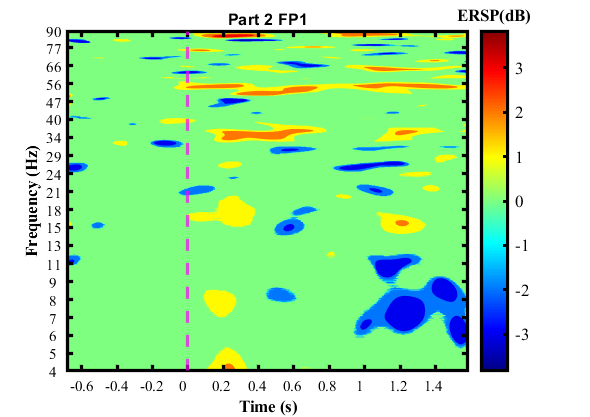

load('01_frequencies.mat'); load('chanlocs.mat');  labels = {chanlocs.labels}'; load('01_time.mat');

%
for j = 1:1:size(ersp_boot,2) %participant
    i = []; figure();
    for i = 1:1:size(ersp_boot,1) %channel
%         subplot(4,6,i); %adapt to the number of channels
        d = []; d = ersp_boot{i,j};
        contourf(d, 'LineColor','none'); % imagesc(d); 
        set(gca,'YDir','normal'); c = colorbar; set(c,'LineWidth',2);

        mi = []; mi = min(min(d)); ma = []; ma = max(max(d));
        if abs(mi)>abs(ma)
            caxis([mi -mi]); %adjust to maximum or minimum
        elseif abs(mi)<abs(ma)
            caxis([-ma ma]); 
        end
        colorTitleHandle = get(c,'Title'); titleString = 'ERSP(dB)';
        set(colorTitleHandle ,'String',titleString, 'FontWeight', 'bold');
        c2=jet(230); colormap(c2); c.FontName = 'Times'; c.FontSize = 10; c.Color = 'k';

        ax = gca; set(ax,'LineWidth',2)
        labelsY = ax.YAxis.TickLabels; % extract
        idx = []; idx = knnsearch(frequencies', (logspace(0.6,1.96,20))');
        set(ax, 'YTick', idx,'XColor', 'k', 'YColor','k');
        labelsY2 = round(frequencies(idx)); ax.YAxis.TickLabels = labelsY2; % set         
        ax.YAxis.FontName = 'Times'; ax.YAxis.FontSize = 10; ax.YAxis.Color = 'k';
        ylabel('Frequency (Hz)', 'FontWeight', 'bold', 'fontname', 'Times',...
            'FontSize', 10,'Color','k')
        
        labelsX = ax.XAxis.TickLabels; % extract
        idx = []; idx = knnsearch(times', [-600; -400; -200; 0; 200;400;600;800;...
            1000;1200;1400]); set(ax, 'XTick', idx);
        labelsX2 = [-0.6; -0.4; -0.2; 0; 0.2; 0.4; 0.6; 0.8; 1; 1.2; 1.4]; 
        ax.XAxis.TickLabels = labelsX2; % set    
        ax.XAxis.FontName = 'Times'; ax.XAxis.FontSize = 10; ax.XAxis.Color = 'k';
        xlabel('Time (s)', 'FontWeight', 'bold','fontname', 'Times',...
            'FontSize', 10,'Color','k');
        
        xline(242, '--m', 'LineWidth', 2);
        title(['Part ' num2str(j) ' ', labels{i,1}]);
        set(gcf, 'Position',  [500.0000  365.8000  472.2000  334.2000])
    end
end

% close all

Figure averaged accross participants

i = []; avg_part = []; 
for i = 1:1:size(ersp_boot,1) %electrodes
    j = []; ersp_boot_part = []; 
    for j = 1:1:size(ersp_boot,2) %participants
       e = []; e = ersp_boot{i,j};
       ersp_boot_part(:,:,j) = e;
    end
    avg = []; avg = mean(ersp_boot_part,3);
    avg_part(:,:,i) = avg;    %3rd dimension = electrodes
end

% save 01_avg_part_ersp_boot.mat avg_part


*Example in case of avg across channels Cz, Pz, CPz, POz. Here, for the sake of computational cost, only one channel is illustrated.*

% clus = [{'Cz'}; {'Pz'}; {'CPz'}; {'POz'}]; idx_cluster = []; 
% 
% for i = 1:1:size(clus,1)
%     chan = clus{i,1}; idx = find(ismember(labels,chan));
%     idx_cluster = [idx_cluster, idx];
% end
% 
% avg_chan = mean(avg_part(:,:,idx_cluster),3);
% 
% save 01_avg_chan_part_ersp_boot.mat avg_chan

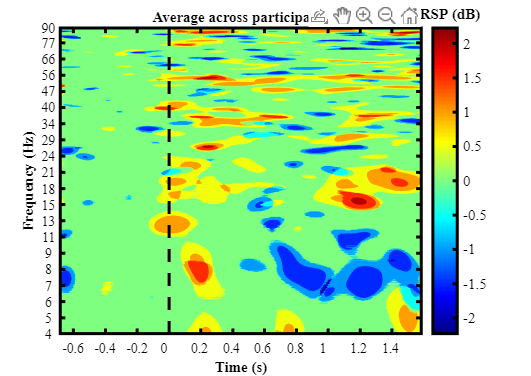

% Figure : replace avg_part by avg_chan in case of having averaged across
% channels
figure(); contourf(avg_part, 'LineColor','none'); set(gca,'YDir','normal');
c = colorbar; set(c,'LineWidth',2); 
mi = []; mi = min(min(avg_part)); ma = []; ma = max(max(avg_part));
if abs(mi) > abs(ma)
   caxis([mi -mi]); %ajustar al maximo o minimo
elseif abs(ma) > abs(mi)
   caxis([-ma ma]); %ajustar al maximo o minimo
else
    caxis([mi ma])
end
colorTitleHandle = get(c,'Title');
titleString = 'ERSP (dB)';
set(colorTitleHandle ,'String',titleString, 'FontWeight', 'bold',...
    'fontname', 'Times', 'FontSize', 10, 'Color', 'k');
c.FontName = 'Times'; c.FontSize = 10; c.Color = 'k';
c2=jet(230); colormap(c2);

ax = gca; set(ax,'LineWidth',2)
labelsY = ax.YAxis.TickLabels; % extract
idx = []; idx = knnsearch(frequencies', (logspace(0.6,1.96,20))');
set(ax, 'YTick', idx,'XColor', 'k', 'YColor','k');
labelsY2 = round(frequencies(idx)); 
ax.YAxis.TickLabels = labelsY2;
ax.YAxis.FontName = 'Times'; ax.YAxis.FontSize = 10; ax.YAxis.Color = 'k';
    ylabel('Frequency (Hz)', 'FontWeight', 'bold', 'fontname', 'Times',...
        'FontSize', 10,'Color','k')
labelsX = ax.XAxis.TickLabels; % extract
idx = []; idx = knnsearch(times', [-600; -400; -200; 0; 200;400;600;800;...
    1000;1200;1400]); set(ax, 'XTick', idx);
labelsX2 = [-0.6; -0.4; -0.2; 0; 0.2; 0.4; 0.6; 0.8; 1; 1.2; 1.4]; 
ax.XAxis.TickLabels = labelsX2; % set    
ax.XAxis.FontName = 'Times'; ax.XAxis.FontSize = 10; ax.XAxis.Color = 'k';
xlabel('Time (s)', 'FontWeight', 'bold','fontname', 'Times',...
    'FontSize', 10,'Color','k');
title('Average across participants', 'FontWeight', 'bold','fontname', 'Times',...
    'FontSize', 10,'Color','k');
xline(242, '--k', 'LineWidth', 2, 'Alpha',1);
set(gcf, 'Position',  [500.0000  365.8000  472.2000  334.2000])

% close all

### Hilbert transform after bandpass filtering

Applying the Hilbert transform to a real-valued signal allows to extract its imaginary part so that its analytical version can be expressed. Like the complex signal obtained after convolution with a complex Morlet wavelet, the analytical signal can be expressed by Euler’s formula.

Contrary to convolution with wavelet, the Hilbert transform does not have the property to bandpass filter the signal. Therefore, the signal should be first bandpass filtered with a filter kernel of center frequency of interest. Bandpass filtering allows higher control over the spectral density of the analytical signal than convolving with a wavelet for which only the peak frequency can be chosen.

*Important consideration when designing filters (here, for a least-squares linear-phase finite impulse response filter (forward and reverse), which PSD is plateau-shaped, centered around the center frequency):*

- The order (length of the filter kernel) must contain several cycles of the center frequency (more cycles, more frequency precision; at least 1 cycle is needed, but 2 to 5 is recommended).

- The highest center frequency must be lower than the Nyquist frequency.

- To optimize frequency precision, the width of transition zones and the distance between lower and upper bounds of the filter (i.e., the length of the PSD plateau) should be defined to minimize both the distance between lower and upper bounds and the sum of squared error between the filter kernel and the ideal filter response. On the contrary, filter kernels with a wide PSD plateau would increase the tempory precision as their representation in time would be shorter. However, the frequency precision would decrease. 

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

*Import previously preprocessed data*

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

MainPath = pwd; folder = uigetdir(); 
fileList = dir(fullfile(folder, '*.set')); L=length(fileList); n = cell(1,L);
for i = 1:L

   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name;
   EEG = []; EEG = pop_loadset('filename', fileList(i).name, 'filepath', MainPath);
   EEG.setname = fileList(i).name; CURRENTSET = []; CURRENTSET = i; 
   [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
%    pop_eegplot(EEG, 1, 1, 1); 
end
eeglab redraw

Create the filter. Here, only one center frequency is presented for the sake of computation time. However, you may insert this code in a loop of all the desidered frequencies. 

% Define filter parameters

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part22-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part22-Human_Anger.fdt'...
pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part33-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Time-Frequency\Part33-Human_Anger.fdt'...


half_fs= ALLEEG(1).srate/2; %Frequencies are scaled by the Nyquist frequency (Nyquist = 1)

freq_center = 12; % in Hz
transition_width = 0.2; % percentage of the lower and upper freq
filter_frequency_spread = 4; % based on the center frequency (Hz)
order = 3*round(ALLEEG(i).srate/(freq_center-filter_frequency_spread));

% Vector of frequencies that define the filter kernel: (1) zero
% frequency, (2) start of the lower transition zone, (3) end of the
% lower transition zone, (3) start of the upper transition zone, (4)
% end of the upper transition zone, (6) Nyquist
% Scaled by the Nyquist frequency
filt_kernel   = [0 (1-transition_width)*(freq_center-filter_frequency_spread) ...
    (freq_center-filter_frequency_spread) (freq_center+filter_frequency_spread)...
    (1+transition_width)*(freq_center+filter_frequency_spread) half_fs]/half_fs;

idealresponse  = [0 0 1 1 0 0]; %1 for frequencie within bandpass, 0 for attenuated frequencies

% (1) order, (2) filter kernel, (3) ideal response
weights  = zscore(firls(order,filt_kernel,idealresponse));

figure();
% Compute its power spectrum
filt_kernel_PSD  = abs(fft(weights));
filt_kernel_PSD  = filt_kernel_PSD./max(filt_kernel_PSD); % normalized to 1 for figure
filt_kernel_freq   = linspace(0,half_fs,ceil(length(filt_kernel_PSD)/2)); % frequencies of filter kernel 
plot(filt_kernel*half_fs,idealresponse,'r', 'LineWidth',1.5);
hold on
plot(filt_kernel_freq,filt_kernel_PSD(1:ceil(length(filt_kernel_PSD)/2)),'b', 'LineWidth',1.5);
xlabel('Frequency (Hz)'); xline(12, LineWidth=1.5, LineStyle="--"); 
Lgnd = legend({'ideal';'best fit'; 'center frequency'});
Lgnd.Position = [0.399525218812701 0.178371477755761 0.251071432386126 0.12619047891526];
Lgnd.FontSize = 9;

freq_filt_idx = dsearchn(filt_kernel_freq',filt_kernel'*half_fs); xlim([0 24]);
title([ 'Sum of Squared Error: ' num2str(sum( (idealresponse-filt_kernel_PSD(freq_filt_idx)).^2 ))])

**How to choose the filter parameters to minimize the Sum of Squared Error**

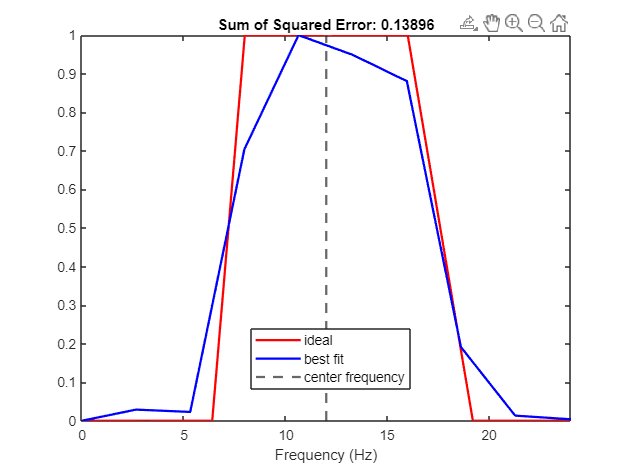

half_fs= ALLEEG(1).srate/2; %Frequencies are scaled by the Nyquist frequency (Nyquist = 1)
freq_center = 12; % in Hz

% Vector of transition width

transition_widths = linspace(0.1,0.5,200); %You can add more samples, but increases computation time
% Vector of filter width (% of the center frequency)
filter_width = linspace(0.1,0.5,200); 

idealresponse  = [0 0 1 1 0 0]; %1 for frequencies within bandpass, 0 for attenuated frequencies
sse = []; 

for i = 1:1:length(transition_widths)
    transition_width = transition_widths(i);
    for j = 1:1:length(filter_width)
        filter_frequency_spread = freq_center*filter_width(j); % based on the center frequency (Hz)
        filt_kernel   = [0 (1-transition_width)*(freq_center-filter_frequency_spread) ...
                            (freq_center-filter_frequency_spread) (freq_center+filter_frequency_spread)...
                            (1+transition_width)*(freq_center+filter_frequency_spread) half_fs]/half_fs;
        order = 3*round((half_fs*2)/(freq_center-filter_frequency_spread));
%         order = 200;
    
        % (1) order, (2) filter kernel, (3) ideal response
        weights  = zscore(firls(order,filt_kernel,idealresponse));

        % filter's power spectrum
        filt_kernel_PSD = abs(fft(weights));
        filt_kernel_PSD = filt_kernel_PSD./max(filt_kernel_PSD); % normalize to 1 for figure
        filt_kernel_freq = linspace(0,half_fs,ceil(length(filt_kernel_PSD)/2)); % frequencies of filter kernel

        freq_filt_idx = dsearchn(filt_kernel_freq',filt_kernel'*half_fs);
        
        sse(i,j) = sum((idealresponse-filt_kernel_PSD(freq_filt_idx)).^2 );
    end
end

figure()
contourf(transition_widths*100,filter_width*100,sse,10,'linecolor','none'); set(gca,'YDir','normal');
xlabel('Transition widths (% of the center frequency)'), ylabel('Filter widths (% of the center frequency)')
set(gca,'clim',[0 1]); c = colorbar; set(c,'LineWidth',2); 
colorTitleHandle = get(c,'Title'); titleString = 'Sum of Squared Error (filter-ideal)'; 
set(colorTitleHandle ,'String',titleString);
c2=jet(230); colormap(c2); title('Center frequency : 12 Hz')

Define the values of transition and filter widths for which the Sum of Squared Error is the lowest. Use those values to create the filter. 

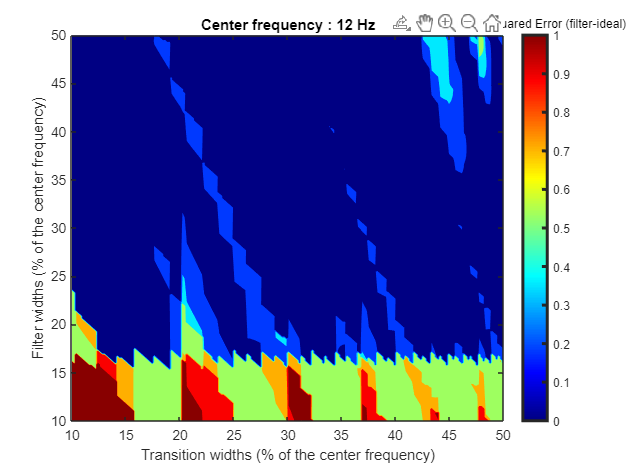

[transwidth_idx, filterwidth_idx] = find(sse==min(min(sse)));

% Define filter parameters
freq_center = 12; % in Hz

transition_width = transition_widths(transwidth_idx); % percentage of the lower and upper freq

filter_frequency_spread = freq_center*filter_width(filterwidth_idx); % based on the center frequency (Hz)

% Vector of frequencies that define the filter kernel: (1) zero
% frequency, (2) start of the lower transition zone, (3) end of the
% lower transition zone, (3) start of the upper transition zone, (4)
% end of the upper transition zone, (6) Nyquist
% Scaled by the Nyquist frequency

filt_kernel   = [0 (1-transition_width)*(freq_center-filter_frequency_spread) ...
                    (freq_center-filter_frequency_spread) (freq_center+filter_frequency_spread)...
                    (1+transition_width)*(freq_center+filter_frequency_spread) half_fs]/half_fs;

order = 3*round((half_fs*2)/(freq_center-filter_frequency_spread));
idealresponse  = [0 0 1 1 0 0]; %1 for frequencie within bandpass, 0 for attenuated frequencies
    
% (1) order, (2) filter kernel, (3) ideal response
weights  = zscore(firls(order,filt_kernel,idealresponse));

% filter's power spectrum
filt_kernel_PSD = abs(fft(weights));
filt_kernel_PSD = filt_kernel_PSD./max(filt_kernel_PSD); % normalize to 1 for figure
filt_kernel_freq = linspace(0,half_fs,ceil(length(filt_kernel_PSD)/2)); % frequencies of filter kernel

freq_filt_idx = dsearchn(filt_kernel_freq',filt_kernel'*half_fs);

sse_optim = sum((idealresponse-filt_kernel_PSD(freq_filt_idx)).^2);

figure();
plot(filt_kernel*half_fs,idealresponse,'r', 'LineWidth',1.5);
hold on
plot(filt_kernel_freq,filt_kernel_PSD(1:ceil(length(filt_kernel_PSD)/2)),'b', 'LineWidth',1.5);
xlabel('Frequency (Hz)'); xline(12, LineWidth=1.5, LineStyle="--"); Lgnd = legend({'ideal';'best fit'; 'center frequency'});
Lgnd.Position = [0.606668075955558 0.673609572993856 0.251071432386126 0.12619047891526];
Lgnd.FontSize = 9; xlim([0 40]);
title(['Sum of Squared Error: ' num2str(sse_optim)])

Option 1: Apply the filter to the data: concatenate the epochs to decrease computation time.

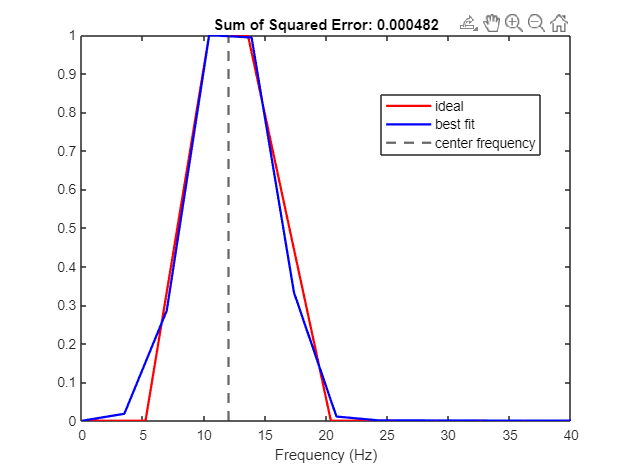

%  Here, only the first channel is filtered to decrease computation
%  time. You may insert a loop to filter data from every sensor

filteredData = []; %time x trials x participants
filteredData_Hamm = []; %time x trials x participants
data_noEp = []; %time x participants

% Apply a Hamming window to the filter kernel to reduce ripples 

weights_hamm = weights.*hamming(length(weights))';

for i = 1:1:size(ALLEEG,2)
    data_noEp(:,i) = squeeze(double(reshape(ALLEEG(i).data(1,:,:),1,ALLEEG(i).pnts*ALLEEG(i).trials)));
    filteredData(:,:,i) = reshape(filtfilt(weights,1,data_noEp(:,i)),ALLEEG(i).pnts,ALLEEG(i).trials);
    filteredData_Hamm(:,:,i) = reshape(filtfilt(weights_hamm,1,data_noEp(:,i)),ALLEEG(i).pnts,ALLEEG(i).trials);
end

Option 2: Apply the filter to the epoched data. May be beneficial to reduce edge artifacts within time window of interest. 

filteredData = []; %time x trials x participants
filteredData_Hamm = [];
filteredData_design = []; 

% Apply a Hamming window to the filter kernel to reduce ripples 
weights_hamm = weights.*hamming(length(weights))';

for i = 1:1:size(ALLEEG,2)
    for j = 1:1:size(ALLEEG(i).data,3)
        %  Here, only the first channel is filtered to decrease computation
        %  time. You may insert a loop to filter data from every sensor
        filteredData(:,j,i) = filtfilt(weights, 1, double((squeeze(ALLEEG(i).data(1,:,j)))));
        filteredData_Hamm(:,j,i) = filtfilt(weights_hamm, 1, double((squeeze(ALLEEG(i).data(1,:,j)))));
    end
end

Apply the Hilbert transform to the filtered data to extract the analytical signal. 

HilbertData = []; % time x trials x participants in first channel
Hilbert_trial_avg = []; % time x participants in first channel

filteredData_tr_avg = squeeze(mean(filteredData, 2));
filteredData_Hamm_tr_avg = squeeze(mean(filteredData_Hamm, 2));

for i = 1:1:size(ALLEEG,2)
    HilbertData(:,:,i) = hilbert(filteredData_Hamm(:,:,i));
    % average accross trials
    Hilbert_trial_avg(:,i) = hilbert(filteredData_Hamm_tr_avg(:,i));
end

Compare with Morlet wavelet 

convolution_result = []; 
for i = 1:1:size(ALLEEG,2)
    for j = 1:1:size(ALLEEG(1).data,3) %trials
        %  Here, only the first channel is convolved to decrease computation
        %  time. You may insert a loop to convolve data from every sensor
        data = []; data = double(ALLEEG(i).data(1,:,j));
        time = -1:1/ALLEEG(i).srate:1; n_data = size(data,2);
        frequency = 12; number_cycles = 15;  
        %The wavelet must taper to 0 (plot(real(wavelet))). 
        % You may increase time (ex.:-2 to 2) if necessary
        wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*(number_cycles/(2*pi*frequency))^2));
        n_wavelet     = length(wavelet); n_convolution = n_wavelet+n_data-1;
        half_of_wavelet_size = (length(wavelet)-1)/2;
        
        fft_data = []; fft_data = fft(data,n_convolution);
        fft_wavelet = fft(wavelet,n_convolution);
        
        convolution = ifft(fft_wavelet.*fft_data,n_convolution);
        convolution_result(:,j,i) = (convolution(half_of_wavelet_size+1:end-half_of_wavelet_size))';
    end
end
% Plot the wavelet to check that it tapers to 0.
figure(); plot(time, real(wavelet), LineWidth=1.5); 
hold on;  plot(time, imag(wavelet), LineWidth=1.5);
legend('Real part', 'Imaginary part'); 
xlabel('Time'); ylabel('Amplitude');
title(['Complex wavelet at ' num2str(frequency), ' Hz - Number of cycles: ' num2str(number_cycles) ])

Average across trials

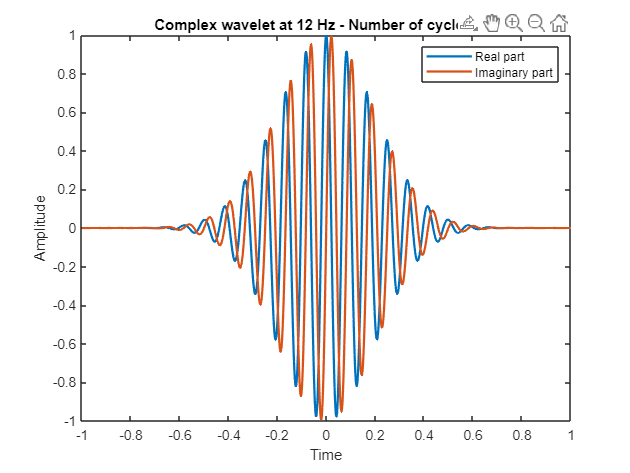

convolution_result_tr_avg = [];
for i = 1:1:size(ALLEEG,2)
    data = []; data = (mean(squeeze(double(ALLEEG(i).data(1,:,:))),2))';
     time = -1:1/ALLEEG(i).srate:1; n_data = size(data,2);
    frequency = 12; number_cycles = 15;  

    %The wavelet must taper to 0 (plot(real(wavelet))). 
    % You may increase time (ex.:-2 to 2) if necessary
    wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*(number_cycles/(2*pi*frequency))^2));
    n_wavelet     = length(wavelet); n_convolution = n_wavelet+n_data-1;
    half_of_wavelet_size = (length(wavelet)-1)/2;
    
    fft_data = []; fft_data = fft(data,n_convolution);
    fft_wavelet = fft(wavelet,n_convolution);
    
    convolution = ifft(fft_wavelet.*fft_data,n_convolution);
    convolution_result_tr_avg(:,i) = (convolution(half_of_wavelet_size+1:end-half_of_wavelet_size))';
end

Plots - Hilbert transform

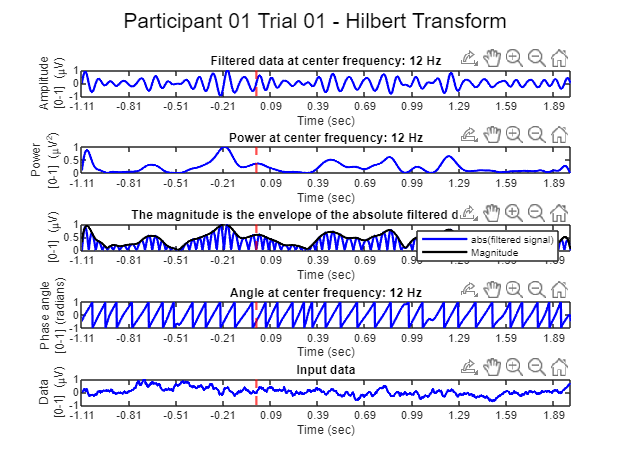

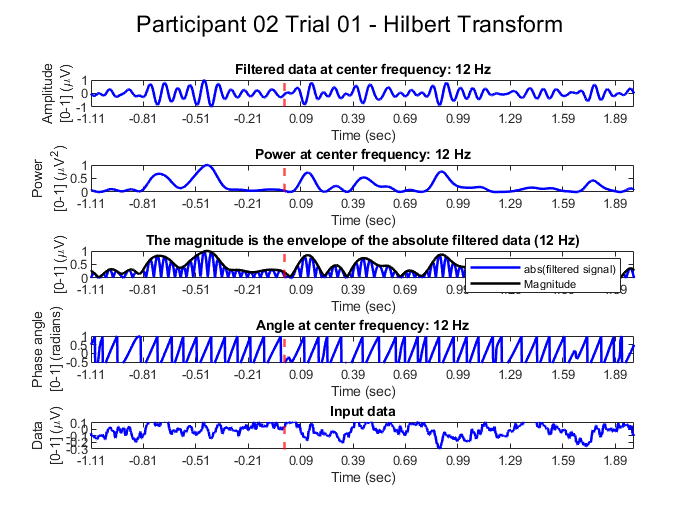

% Normalize data for plot 

time = ALLEEG(1).times/1000; %Time is seconds
for i = 1:1:size(ALLEEG,2)
    figure('WindowState','maximized')
    subplot(5,1,1)
    plot(time,real(HilbertData(:,1,i))./max(real(HilbertData(:,1,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Amplitude' ; '[0-1] (\muV)'});
    title('Filtered data at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,2)
    plot(time,(abs(HilbertData(:,1,i)).^2)./max((abs(HilbertData(:,1,i)).^2)), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Power' ; '[0-1] (\muV^2)'});
    title('Power at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,3)
    p1 = plot(time,abs(real(HilbertData(:,1,i))./max(abs(real(HilbertData(:,1,i))))),...
        LineWidth=1.5, Color="b");
    hold on 
    p2 = plot(time,abs(HilbertData(:,1,i))./max(abs(HilbertData(:,1,i))), ...
        LineWidth=1.5, Color="k");
    title('The magnitude is the envelope of the absolute filtered data (12 Hz)');
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    legend('show', [p1; p2], {'abs(filtered signal)', 'Magnitude'});
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xlabel('Time (sec)'), ylabel({'[0-1] (\muV)'});
    
    subplot(5,1,4)
    plot(time,angle(HilbertData(:,1,i))./max(angle(HilbertData(:,1,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Phase angle' ; '[0-1] (radians)'});
    title('Angle at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,5)
    plot(time, double(ALLEEG(i).data(1,:,1))./max(double(ALLEEG(1).data(1,:,1))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Data' ; '[0-1] (\muV)'});
    title('Input data');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    sgtitle(['Participant ' num2str(i,'%02.f'), ' Trial 01 - Hilbert Transform'])
end

Average across trials -  Hilbert transform

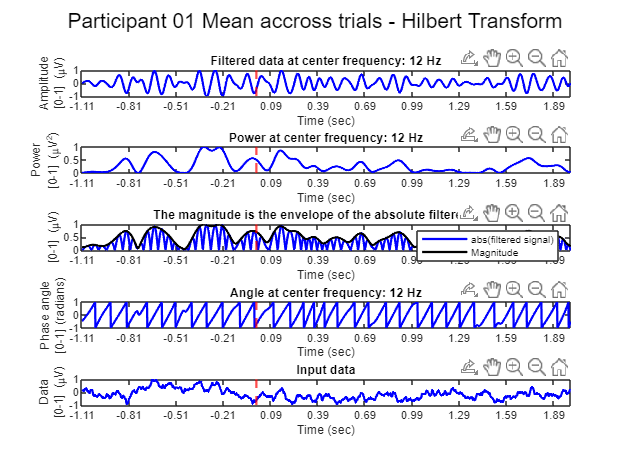

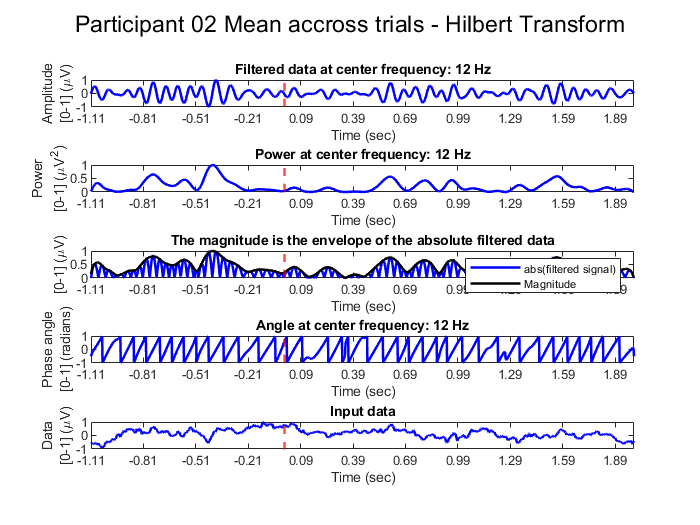

for i = 1:1:size(ALLEEG,2)
    figure('WindowState','maximized')
    subplot(5,1,1)
    plot(time,real(Hilbert_trial_avg(:,i))./max(real(Hilbert_trial_avg(:,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Amplitude' ; '[0-1] (\muV)'});
    title('Filtered data at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,2)
    plot(time,(abs(Hilbert_trial_avg(:,i)).^2)./max((abs(Hilbert_trial_avg(:,i)).^2)), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Power' ; '[0-1] (\muV^2)'});
    title('Power at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,3)
    p1 = plot(time,abs(real(Hilbert_trial_avg(:,i))./max(abs(real(Hilbert_trial_avg(:,i))))),...
        LineWidth=1.5, Color="b");
    hold on 
    p2 = plot(time,abs(Hilbert_trial_avg(:,i))./max(abs(Hilbert_trial_avg(:,i))), ...
        LineWidth=1.5, Color="k");
    title('The magnitude is the envelope of the absolute filtered data');
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    legend('show', [p1; p2], {'abs(filtered signal)', 'Magnitude'});
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xlabel('Time (sec)'), ylabel({'[0-1] (\muV)'});
    
    subplot(5,1,4)
    plot(time,angle(Hilbert_trial_avg(:,i))./max(angle(Hilbert_trial_avg(:,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Phase angle' ; '[0-1] (radians)'});
    title('Angle at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,5)
    data = mean(double(ALLEEG(i).data(1,:,:)),3);
    plot(time, data./max(data), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Data' ; '[0-1] (\muV)'});
    title('Input data');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    sgtitle(['Participant ' num2str(i,'%02.f'), ' Mean accross trials - Hilbert Transform'])
end

Plots - Wavelet convolution

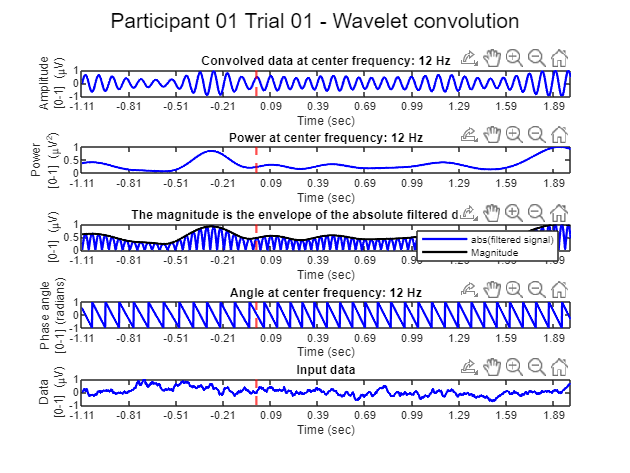

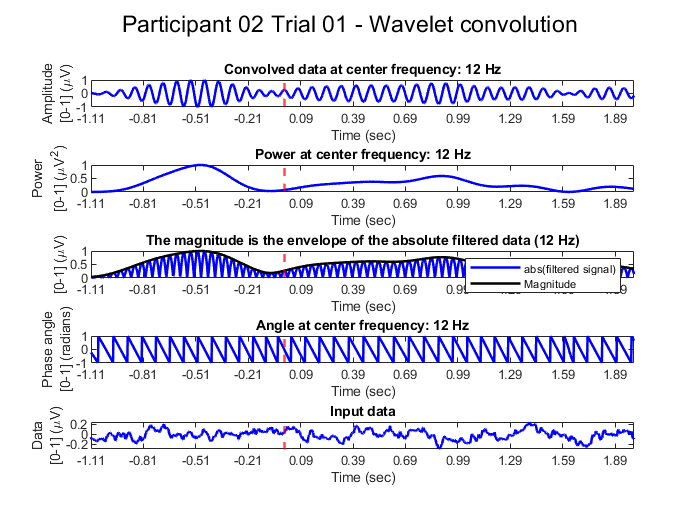

% Normalize data for plot 

time = ALLEEG(1).times/1000; %Time is seconds
for i = 1:1:size(ALLEEG,2)
    figure('WindowState','maximized')
    subplot(5,1,1)
    plot(time,real(convolution_result(:,1,i))./max(real(convolution_result(:,1,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Amplitude' ; '[0-1] (\muV)'});
    title('Convolved data at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,2)
    plot(time,(abs(convolution_result(:,1,i)).^2)./max((abs(convolution_result(:,1,i)).^2)), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Power' ; '[0-1] (\muV^2)'});
    title('Power at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,3)
    p1 = plot(time,abs(real(convolution_result(:,1,i))./max(abs(real(convolution_result(:,1,i))))),...
        LineWidth=1.5, Color="b");
    hold on 
    p2 = plot(time,abs(convolution_result(:,1,i))./max(abs(convolution_result(:,1,i))), ...
        LineWidth=1.5, Color="k");
    title('The magnitude is the envelope of the absolute filtered data (12 Hz)');
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    legend('show', [p1; p2], {'abs(filtered signal)', 'Magnitude'});
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xlabel('Time (sec)'), ylabel({'[0-1] (\muV)'});
    
    subplot(5,1,4)
    plot(time,angle(convolution_result(:,1,i))./max(angle(convolution_result(:,1,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Phase angle' ; '[0-1] (radians)'});
    title('Angle at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,5)
    plot(time, double(ALLEEG(i).data(1,:,1))./max(double(ALLEEG(1).data(1,:,1))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Data' ; '[0-1] (\muV)'});
    title('Input data');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    sgtitle(['Participant ' num2str(i,'%02.f'), ' Trial 01 - Wavelet convolution'])
end

Average across trials - Wavelet convolution

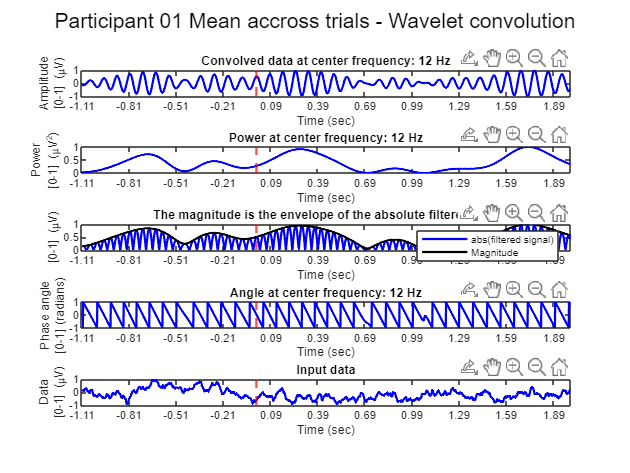

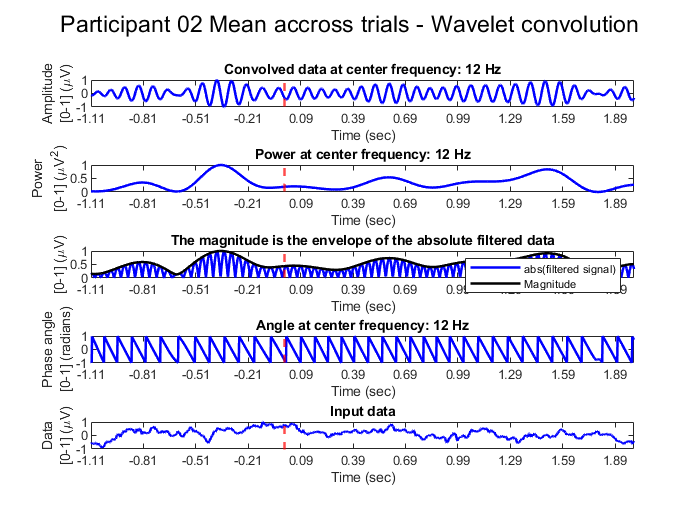

for i = 1:1:size(ALLEEG,2)
    figure('WindowState','maximized')
    subplot(5,1,1)
    plot(time,real(convolution_result_tr_avg(:,i))./max(real(convolution_result_tr_avg(:,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Amplitude' ; '[0-1] (\muV)'});
    title('Convolved data at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,2)
    plot(time,(abs(convolution_result_tr_avg(:,i)).^2)./max((abs(convolution_result_tr_avg(:,i)).^2)), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Power' ; '[0-1] (\muV^2)'});
    title('Power at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,3)
    p1 = plot(time,abs(real(convolution_result_tr_avg(:,i))./max(abs(real(convolution_result_tr_avg(:,i))))),...
        LineWidth=1.5, Color="b");
    hold on 
    p2 = plot(time,abs(convolution_result_tr_avg(:,i))./max(abs(convolution_result_tr_avg(:,i))), ...
        LineWidth=1.5, Color="k");
    title('The magnitude is the envelope of the absolute filtered data');
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    legend('show', [p1; p2], {'abs(filtered signal)', 'Magnitude'});
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xlabel('Time (sec)'), ylabel({'[0-1] (\muV)'});
    
    subplot(5,1,4)
    plot(time,angle(convolution_result_tr_avg(:,i))./max(angle(convolution_result_tr_avg(:,i))), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Phase angle' ; '[0-1] (radians)'});
    title('Angle at center frequency: 12 Hz');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    
    subplot(5,1,5)
    data = mean(double(ALLEEG(i).data(1,:,:)),3);
    plot(time, data./max(data), LineWidth=1.5, Color="b");
    xlabel('Time (sec)'), ylabel({'Data' ; '[0-1] (\muV)'});
    title('Input data');
    xlim([min(time) max(time)]); xticks(min(time):0.3:max(time)); 
    xline(0,LineStyle="--", LineWidth=1.5, Color="r");
    sgtitle(['Participant ' num2str(i,'%02.f'), ' Mean accross trials - Wavelet convolution'])
end

### **Note 01: several frequencies**

To compute the power information accross time for several frequencies, the previous code may be looped for a vector of frequencies. That is, the data may be bandpass filtered into several frequency bands (centered on various frequencies). Frequency bands may overlap to increase the smoothness of the results and subsequent plots. However, too much overlapping would increase computation time without increasing information. Generally, 25 to 75% of overlap may be adequate. Time and frequency precisions should be adjusted according to the frequencies. That is, the width of the filter should be increased with frequencies to conserve time precision from low to high frequencies. 

### **Note 02: statistical tests to compare with baseline**

As presented in the first section (*Morlet wavelet*), data may be compared to a baseline, and only values of power over time significantly different from baseline may be considered for further statistical analyses. Permutations may be applied for comparison with baseline. Please refer to the PDF and mlx files ("*Permutation statistics*") for a detailed explanation and corresponding codes. 

### Short-time Fourrier and tapering

The short-time Fourrier transform is an extension of the Fourrier transform to extract information of power spectrum in the time domain. Also, as wavelets, the stationnarity of EEG data is assumed over shorter and reasonnable time windows. 

Please, see the PowerPoint slide dedicated to it for details about this methods (TheoreticalExplanations.pdf). Codes for the short-time Fourrier transform will not be presented here because of the following two disadvantages of this technique:

- Tapering of every short segments by a window to reduce edges artifacts (e.g., Hanning; must taper to 0) is needed. As a comparison, no edges artifacts may arise with wavelets thanks to the profile of the kernel (less amplitude at the extermities). The loss of signal due to tapering might be regularized by overlaping of time segments. However, it increases computation cost.

- The algorithm outputs the phase parameter for each time window and frequency (phase value when t=0) instead of the phase vector through time.

Note: multitapers may be applied to increase the signal-to-noise ratio. It consists of using several tapers of different spectral and temporal characteristics to generate a more accurate overview of the information embedded into the data. The results from the Fourrier transform after every tapering methods are finally averaged. Nevertheless, mutitapering induces temporal and spectral smoothing. Therefore, it may be beneficial for high frequencies (~ more than 30 Hz) for which the spectrum tend to be wider, but may not be optimal for lower frequencies. Also, whenever time precision is requiered, multitaping may not be the best option. 

### Inter-trial phase coherence (ITC)

To compute ITC may be useful to assess the consistence of phase between several signals (generally trials). **The ITC is in range [0-1] with 0 the highest degree of inconsistency and 1 perfect phase consistency. **

The ITC may complement Event-Related Potentials (ERP) analysis, providing phase information. Please refer to the documents *EventRelatedPotentials.pdf *and *EventRelatedPotentials.mlx *for a detailed explanation of ERP.

According to Euler's formula: 

`Magnitude * e^i*phase = Magnitude [cos(phase) + i sin(phase)], `

`where e is the base of the natural logarithm (~2.72)`

Within the computation of ITC, only the phase information is relevant, therefore, to extract it, the Euler's formula can be divided by the value of the magnitude: 

`e^i*phase = [cos(phase) + i sin(phase)]`

**The ITC is simply the absolute value of the mean of **`e^i*phase = [cos(phase) + i sin(phase)] `**accross trials**. 

Let's consider two phase value in a polar plane: 

- phase01 = pi, and phase02 = 0, thus **2 opposite vectors**. In this case: 

- `e^i*phase01 = [cos(phase01) + i sin(phase01)] = -1`

- `e^i*phase02 = [cos(phase02) + i sin(phase02] = 1`

- `ITC = |(-1+1)/2| = 0`

- phase02 = 0, and phase02 = 0, thus **2 perfectly consistent phase vectors**. In this case: 

- `e^i*phase01 = [cos(phase01) + i sin(phase01)] = 1`

- `e^i*phase02 = [cos(phase02) + i sin(phase02] = 1`

- `ITC = |(1+1)/2| = 1`

Information about ITC is available from the output variables of the *newtimef* function of EEGLab (please see the *Morlet wavelet* section of the present document).

Outline significant ITC

clc; clear; close all; load('01_itcabs_tot.mat'); load('01_itcboot_tot.mat');

itc_boot = cell(size(itcabs_tot,1),size(itcabs_tot,2));
for m = 1:1:size(itcabs_tot,2) %participants
    for k = 1:1:size(itcabs_tot,1) %sensors
        itcabs_tot2 = []; itcabs_tot2 = itcabs_tot{k,m}; 
        f = []; f = itcboot_tot{k,m}; i = []; 
        for i = 1:1:size(itcabs_tot2,2) %time
            j = []; 
            for j = 1:1:size(itcabs_tot2,1) %frequencies
                e = []; e = itcabs_tot2(j,i);
                % Whenever itc is superior to the
                % threshold for significance (non-significant data)
                if e < f(j,1) == 1 
                    itcabs_tot2(j,i) = 0;
                end
            end
        end
        itc_boot{k,m} = itcabs_tot2;
    end
end
% save 01_itc_boot.mat itc_boot

Figure per participant and channel. Remember that here, only data from the first sensor have been analysed to lower computation cost. 

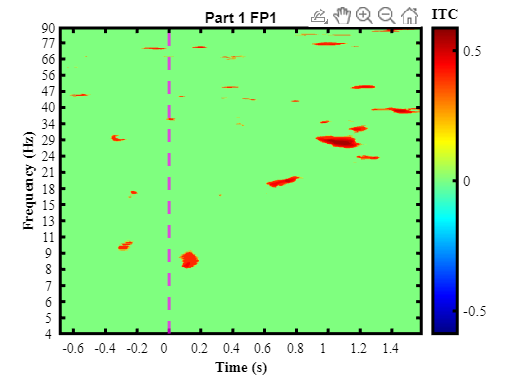

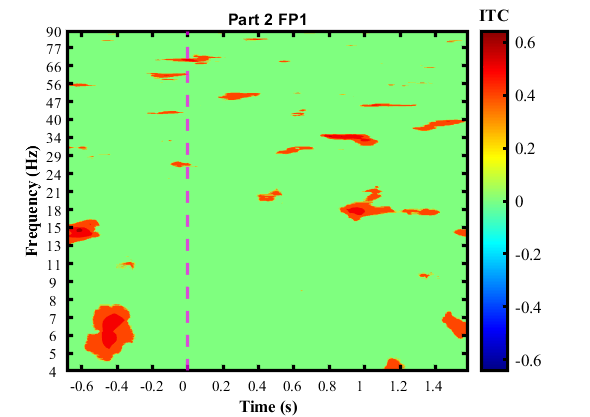

load('01_frequencies.mat'); load('chanlocs.mat');  labels = {chanlocs.labels}'; load('01_time.mat');

for j = 1:1:size(itc_boot,2) %participant
    i = []; figure();
    for i = 1:1:size(itc_boot,1) %channel
%         subplot(4,6,i); %adapt to the number of channels
        d = []; d = itc_boot{i,j};
        contourf(d, 'LineColor','none'); % imagesc(d); 
        set(gca,'YDir','normal'); c = colorbar; set(c,'LineWidth',2);

        mi = []; mi = min(min(d)); ma = []; ma = max(max(d));
        if abs(mi)>abs(ma)
            caxis([mi -mi]); %adjust to maximum or minimum
        elseif abs(mi)<abs(ma)
            caxis([-ma ma]); 
        end
        colorTitleHandle = get(c,'Title'); titleString = 'ITC';
        set(colorTitleHandle ,'String',titleString, 'FontWeight', 'bold');
        c2=jet(230); colormap(c2); c.FontName = 'Times'; c.FontSize = 10; c.Color = 'k';

        ax = gca; set(ax,'LineWidth',2)
        labelsY = ax.YAxis.TickLabels; % extract
        idx = []; idx = knnsearch(frequencies', (logspace(0.6,1.96,20))');
        set(ax, 'YTick', idx,'XColor', 'k', 'YColor','k');
        labelsY2 = round(frequencies(idx)); ax.YAxis.TickLabels = labelsY2; % set         
        ax.YAxis.FontName = 'Times'; ax.YAxis.FontSize = 10; ax.YAxis.Color = 'k';
        ylabel('Frequency (Hz)', 'FontWeight', 'bold', 'fontname', 'Times',...
            'FontSize', 10,'Color','k')
        
        labelsX = ax.XAxis.TickLabels; % extract
        idx = []; idx = knnsearch(times', [-600; -400; -200; 0; 200;400;600;800;...
            1000;1200;1400]); set(ax, 'XTick', idx);
        labelsX2 = [-0.6; -0.4; -0.2; 0; 0.2; 0.4; 0.6; 0.8; 1; 1.2; 1.4]; 
        ax.XAxis.TickLabels = labelsX2; % set    
        ax.XAxis.FontName = 'Times'; ax.XAxis.FontSize = 10; ax.XAxis.Color = 'k';
        xlabel('Time (s)', 'FontWeight', 'bold','fontname', 'Times',...
            'FontSize', 10,'Color','k');
        
        xline(242, '--m', 'LineWidth', 2);
        title(['Part ' num2str(j) ' ', labels{i,1}]);
        set(gcf, 'Position',  [500.0000  365.8000  472.2000  334.2000])
    end
end

% close all

Figure averaged accross participants

i = []; avg_part = []; 
for i = 1:1:size(itc_boot,1) %electrodes
    j = []; itc_boot_part = []; 
    for j = 1:1:size(itc_boot,2) %participants
       e = []; e = itc_boot{i,j};
       itc_boot_part(:,:,j) = e;
    end
    avg = []; avg = mean(itc_boot_part,3);
    avg_part(:,:,i) = avg;    %3rd dimension = electrodes
end

% save 01_avg_part_itc_boot.mat avg_part

*Example in case of avg across channels Cz, Pz, CPz, POz. Here, for the sake of computational cost, only one channel is illustrated.*

% clus = [{'Cz'}; {'Pz'}; {'CPz'}; {'POz'}]; idx_cluster = []; 
% 
% for i = 1:1:size(clus,1)
%     chan = clus{i,1}; idx = find(ismember(labels,chan));
%     idx_cluster = [idx_cluster, idx];
% end
% 
% avg_chan = mean(avg_part(:,:,idx_cluster),3);
% 
% save 01_avg_chan_part_itc_boot.mat avg_chan

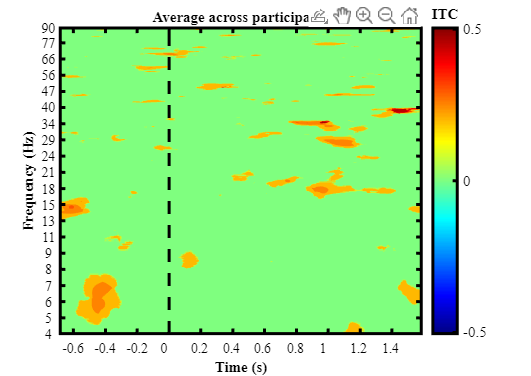

% Figure : replace avg_part by avg_chan in case of having averaged across
% channels
figure(); contourf(avg_part, 'LineColor','none'); set(gca,'YDir','normal');
c = colorbar; set(c,'LineWidth',2); 
mi = []; mi = min(min(avg_part)); ma = []; ma = max(max(avg_part));
if abs(mi) > abs(ma)
   caxis([mi -mi]); %ajustar al maximo o minimo
elseif abs(ma) > abs(mi)
   caxis([-ma ma]); %ajustar al maximo o minimo
else
    caxis([mi ma])
end
colorTitleHandle = get(c,'Title');
titleString = 'ITC';
set(colorTitleHandle ,'String',titleString, 'FontWeight', 'bold',...
    'fontname', 'Times', 'FontSize', 10, 'Color', 'k');
c.FontName = 'Times'; c.FontSize = 10; c.Color = 'k';
c2=jet(230); colormap(c2);

ax = gca; set(ax,'LineWidth',2)
labelsY = ax.YAxis.TickLabels; % extract
idx = []; idx = knnsearch(frequencies', (logspace(0.6,1.96,20))');
set(ax, 'YTick', idx,'XColor', 'k', 'YColor','k');
labelsY2 = round(frequencies(idx)); 
ax.YAxis.TickLabels = labelsY2;
ax.YAxis.FontName = 'Times'; ax.YAxis.FontSize = 10; ax.YAxis.Color = 'k';
    ylabel('Frequency (Hz)', 'FontWeight', 'bold', 'fontname', 'Times',...
        'FontSize', 10,'Color','k')
labelsX = ax.XAxis.TickLabels; % extract
idx = []; idx = knnsearch(times', [-600; -400; -200; 0; 200;400;600;800;...
    1000;1200;1400]); set(ax, 'XTick', idx);
labelsX2 = [-0.6; -0.4; -0.2; 0; 0.2; 0.4; 0.6; 0.8; 1; 1.2; 1.4]; 
ax.XAxis.TickLabels = labelsX2; % set    
ax.XAxis.FontName = 'Times'; ax.XAxis.FontSize = 10; ax.XAxis.Color = 'k';
xlabel('Time (s)', 'FontWeight', 'bold','fontname', 'Times',...
    'FontSize', 10,'Color','k');
title('Average across participants', 'FontWeight', 'bold','fontname', 'Times',...
    'FontSize', 10,'Color','k');
xline(242, '--k', 'LineWidth', 2, 'Alpha',1);
set(gcf, 'Position',  [500.0000  365.8000  472.2000  334.2000])

% close all